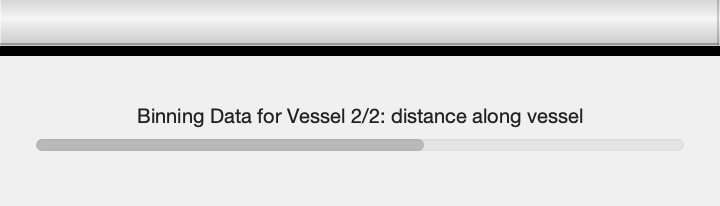

idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



idx2 =

  0×1 empty double column vector



idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



idx2 =

  0×1 empty double column vector



tic
clc; clear all; close all;

% Exported Data Format: [ Vessel#  Frame#  MinFrameDistance MaxFrameDistance  ObjectDensity  ]

%% Import Data

% .txt file (Recommended for speed):

% Input tau data folder name (INCLUDE FOLDER PATH AND NAME):
Tau_sourcefolder = '/Users/zacharyhoglund/Downloads/Tracing Analysis Testing/Tangle_distance_data';

% Input distance transform data folder name for volume calculation (INCLUDE FOLDER PATH AND NAME):
Distance_sourcefolder = '/Users/zacharyhoglund/Downloads/Tracing Analysis Testing/tangle_volume_data';

% Max Distance From Vessel (in microns) (Recommended Value 30):

ves_dist = [ 100 ];

min_dist = [ -10 ];

% Resolution in microns? (Recommended Value: 1):

res = [ 1 ];

% Frame width (# Microns):

frame_w = [ 10 ];

% Voxel Size

% Voxel Size:  [   X     Y    Z   ]
voxel =        [ 0.621 0.621 2.50 ];

% Data Output Name (True, unshuffled data only) (Include Name + Path):
% Vessel number and data type will be appended, so do not include in names.
% NEED FOLDER WITH SAME NAME FOR EACH DATA TYPE: XDATA, YDATA, AND ERRORS
% ex. you need folders stat_data_xdata, stat_data_ydata, and
% stat_data_errors if stat_data is the folder name.

% Folder:
outputfoldername = '/Users/zacharyhoglund/Downloads/Tracing Analysis Testing/TEST_tangle_density_data';

% File:
outputname = 'Human2267_tangle_density_data';

% % Set number of bins by increment of intensity
% nbins = round((max(Tau_data(:,4)) - min(Tau_data(:,4)))/50);

%% Load Data

% # Bins along vessel
nbins_length = 5;

f = waitbar(0,'Calculating Statistics: Reading Data 0 %');

fcontent = dir(fullfile(Tau_sourcefolder, '*.txt')); %fcontent is a column vector of structures

l1 = 1;

Tau_data = [];

Distance_data = [];

n = length(fcontent');

endrow = 0;
final_data = [];

for b = 1:2

    sizes = [];
        n1 = b;
        n2 = b;
        Tau_data = [];
        bin_edges = [];
        surface_data = [];
        bin_numbers = [];
        clc
        % close all

fcontent = dir(fullfile(Tau_sourcefolder, '*.txt')); %fcontent is a column vector of structures

%i = 7;

   filename = fcontent(b).name;
   Tau_data_single = [];
   Tau_data_single = readmatrix(fullfile(Tau_sourcefolder,filename));
   [r, c] = size(Tau_data_single);
   l2 = l1 + r - 1;
   Tau_data(l1:l2,:) = Tau_data_single;
   l1 = 1;

 

% Remove data where Tau is within blood vessel and greater than ves_dist
% away

Tau_data_backup = Tau_data;
edges = [min_dist ves_dist];

idx = discretize(Tau_data(:,6),edges)

idx2 = find(isnan(idx))
Tau_data(idx2,:) = [];


if isempty(Tau_data)
    Tau_data = zeros(1,6)-min_dist-100;
end

% Read Distance Data

  waitbar(0,f,'Reading Data: Reading Volume Data');

fcontent = dir(fullfile(Distance_sourcefolder, '*.txt')); %fcontent is a column vector of structures

   filename = fcontent(b).name;
   Distance_data_single = [];
   Distance_data_single = readmatrix(fullfile(Distance_sourcefolder,filename));
   Distance_data = [Distance_data_single(:,1:3) zeros(length(Distance_data_single(:,1)),1) Distance_data_single(:,5) Distance_data_single(:,4)];

  




waitbar(0.1,f,'Calculating Statistics: Preparing Data');

% % if isempty(Tau_data)
% %     continue
% % end

% Remove data where Tau is within blood vessel and greater than ves_dist
% away
Distance_data_backup = Distance_data;

Tau_data_backup = Tau_data;

%% Bin Data by Surface Frames

% vesnum = vessel ID    g = frame ID

fcontent = dir(fullfile(Tau_sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename = fcontent(b).name;
[pathstr,name,ext] = fileparts(filename);

name_parts = regexp(name,'_','split');
vesnum = str2num(name_parts{3});



%%

waitbar(0.3,f,sprintf('Binning Data for Vessel %d/%d: distance away from vessel',b,n));

%% bin by distance away

edges_away = min_dist-0.5:res:ves_dist+0.5;

idx_tau_away = discretize(Tau_data(:,6),edges_away);

idx_dist_away = discretize(Distance_data(:,6),edges_away);

waitbar(0.6,f,sprintf('Binning Data for Vessel %d/%d: distance along vessel',b,n));

% Bin by distance along

maxlength = (ceil(max(Distance_data(:,5)/frame_w))*frame_w);

edges_along = 0:frame_w:maxlength;

idx_tau_along = discretize(Tau_data(:,5),edges_along);

idx_dist_along = discretize(Distance_data(:,5),edges_along);

Tau_data(any(isnan(Tau_data), 2), :) = [];
Distance_data(any(isnan(Distance_data), 2), :) = [];

%% Store bin coordinates for each point

Tau_data(:,7:8) = [idx_tau_along idx_tau_away];

Distance_data(:,7:8) = [idx_dist_along idx_dist_away];

Tau_data(any(isnan(Tau_data), 2), :) = [];
Distance_data(any(isnan(Distance_data), 2), :) = [];

Tau_data_backup2 = Tau_data;

final_data(endrow+1:endrow+length(edges_along),:) = zeros(length(edges_along),length(edges_away)+3);

for i = 1:length(edges_along)

    final_data(endrow+i,1:4) = [vesnum i i*frame_w-frame_w  i*frame_w];

end


for i = 1:length(Tau_data(:,1))

    dist_data_temp = Distance_data(:,7:8);
    tau_data_temp = Tau_data(:,7:8);

    edges1 = [tau_data_temp(i,1)-0.5;tau_data_temp(i,1)+0.5];

    idx_tau = discretize(tau_data_temp(:,1),edges1);
    idx_dist = discretize(dist_data_temp(:,1),edges1);

    tau_data_temp(:,1) = idx_tau;
    dist_data_temp(:,1) = idx_dist;

    edges2 = [tau_data_temp(i,2)-0.5;tau_data_temp(i,2)+0.5];

    idx_tau2 = discretize(tau_data_temp(:,2),edges2);
    idx_dist2 = discretize(dist_data_temp(:,2),edges2);

    tau_data_temp(:,2) = idx_tau2;
    dist_data_temp(:,2) = idx_dist2;

    tau_data_temp(any(isnan(tau_data_temp), 2), :) = [];
    dist_data_temp(any(isnan(dist_data_temp), 2), :) = [];

    volume = length(dist_data_temp(:,1))*(voxel(1)*voxel(2)*voxel(3));

    density = length(tau_data_temp(:,1))/volume;

    final_data(endrow+Tau_data(i,7),Tau_data(i,8)+4) = density;

    tau_data_temp = [];
    dist_data_temp = [];
    idx_tau = [];
    idx_dist = [];
    idx_tau2 = [];
    idx_dist2 = [];

end


endrow = length(final_data(:,1));
Tau_data = [];
Distance_data = [];

end

%% Headers
sampleID = name_parts{1};
intensity_headers = [min_dist:ves_dist];
intensity_headerstemp = {};
for i = 1:length(intensity_headers)
    intensity_headerstemp(:,i) = {append(sprintf('%g',intensity_headers(1,i)),' um Density (#/um^3)')};
end
intensity_headers = intensity_headerstemp;
headers = cell2table({ sampleID 'Vessel#'  'Frame#'  'MinFrameDistance' 'MaxFrameDistance' intensity_headers{:}});


## Save Data (Add header export in separate file)


writetable(headers,append(outputfoldername,'/',outputname,'_HEADERS.csv'));
writematrix(final_data,append(outputfoldername,'/',outputname,'.csv'));

toc

Elapsed time is 590.160599 seconds.
